**Lab 7**

**Problem 1: ***Make a stacked histogram plot for the feature variable: mass*

Let's first reimport all of the data.

higgsData = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcdData = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
hPT = higgsData(1,:);
qPT = qcdData(1,:);

PT is the transverse (xy) momentum, given by pt = sqrt(px^2 + py^2), where px and py are the momenta along x and y.

hETA = higgsData(2,:);
qETA = qcdData(2,:);

ETA is the pseudorapidity, given by -ln(tan(ø/2))-0.5ln((abs(p)+pl)/(abs(p)-pl))

hPHI = higgsData(3,:);
qPHI = qcdData(3,:);

PHI is the azimuthal angle, given by arccos(x/r)

hMASS = higgsData(4,:);
qMASS = qcdData(4,:);

MASS is the mass invariant, given by E^2 = p^2 + m^2 (natural units).

hEE2 = higgsData(5,:);
qEE2 = qcdData(5,:);

EE2 is the 2-point ECF ratio, given by sum over i<j in J of (p_t,i * p_t,j * deltaR_ij * 1/(p_t,J)^2). This observable shows 2-prong particle decay.

hEE3 = higgsData(6,:);
qEE3 = qcdData(6,:);

EE3 is the 3-point ECF ratio, given by sum over i<j<k in J of (p_t,i * p_t,j * p_t,k * deltaR_ij * deltaR_ik * deltaR_jk * 1/(p_t,J)^3). This observable shows 3-prong particle decay.

hD2 = higgsData(7,:);
qD2 = qcdData(7,:);

D2 is the 3-to-2 point ECF ratio, given by EE3/(EE2)^3

hANG = higgsData(8,:);
qANG = qcdData(8,:);

ANG is the angularity, given by 1/m_J * sum over i in J of (E_i * cos^3(ø_i) / (sin^2(ø_i)))

hT1 = higgsData(9,:);
qT1 = qcdData(9,:);

T# variables are subjettiness, where # is the n in n-subjettiness, and Tnm is Tn/Tm.

hT2 = higgsData(10,:);
qT2 = qcdData(10,:);

hT3 = higgsData(11,:);
qT3 = qcdData(11,:);

hT21 = higgsData(12,:);
qT21 = qcdData(12,:);

hT32 = higgsData(13,:);
qT32 = qcdData(13,:);

hKTDELTAR = higgsData(14,:);
qKTDELTAR = qcdData(14,:);

Let's create a histogram plot containing both the background and the data of mass.

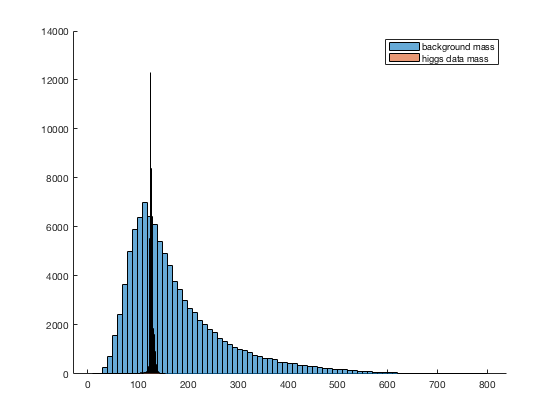

figure;
hold on
histogram(qMASS);
histogram(hMASS);
legend('background mass','higgs data mass');

*Evaluate expected significance without any event selection.*

*Use Poisson statistics for significance calculation.*

We are to assume that both of these follow a Poisson distribution. The statistics for the Poisson distributions in question are given in the "dataset" subsection of the assignment. For my data, N_higgs = 50, N_qcd = 2000.

N_higgs = 50;
N_qcd = 2000;
N_tot = N_higgs + N_qcd;

Make a poisson distribution centered on N_qcd, then find the significance of N_tot.

poissonQCD = makedist('Poisson',"lambda",N_qcd);
prob = 1 - cdf(poissonQCD,N_tot)

prob = 0.1296

s_Ntotqcd = icdf('Normal',1-prob,0,1)

s_Ntotqcd = 1.1282

The significance that I find for qcd is 1.13 sigma, which is not enough to claim a discovery.

*Compare your number of 𝑁𝐻𝑖𝑔𝑔𝑠/(√𝑁𝑄𝐶𝐷). If they are equivalent, explain your findings.*

N_higgs/sqrt(N_qcd)

ans = 1.1180

I actually don't understand what this question is asking me. N_higgs/sqrt(N_qcd) that I find is 1.12, which is different from the sigma we find above (and I don't see how they could be the same). I'm not sure what this number means, and so don't really understand what is meant by explaining my findings.

**Problem 2: ***Identify mass cuts to optimize the expected significance.*

*Try different mass cuts systematically*

*Evaluate expected significance for each set of mass cuts*

*Identify the set of the mass cuts which give you the highest significance.*

These directions are exceptionally awful. Literally nothing makes sense to me.

First, I think I need to calculate the total number of events in the background histogram, as well as the higgs data.

N_qcd_full = 2000;
N_higgs_full = 50;

Now that I have the total number of events in the histograms, I want to select a range such that a lot of my higgs data is there, while trying to get as little of the background data as possible. I want to test a range somewhere between 100 and 150, so I will replot my histograms with that as the xlimit.

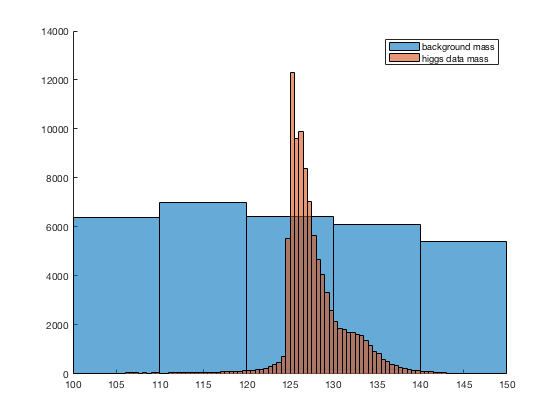

figure;
hold on
histogram(qMASS);
histogram(hMASS);
legend('background mass','higgs data mass');
xlim([100 150]);

From this plot, it looks like a range of 125-128 encapsulates a lot of the higgs data, and not so much of the background data. This is the "cut" that I want to evaluate.

For this "cut," I will calculate the number of higgs events present and the number of background events present, remembering to rescale these numbers.

N_qcd_range = length(nonzeros(qMASS >= 125 & qMASS <= 128))/50

N_qcd_range = 37.6600

N_higgs_range = length(nonzeros(hMASS >= 125 & hMASS <= 128))/2000

N_higgs_range = 26.4470

Now, I need to create new Poisson distributions for this selected data range.

N_higgs_new = N_higgs * (N_higgs_range/N_higgs_full)

N_higgs_new = 26.4470

N_qcd_new = N_qcd * (N_qcd_range/N_qcd_full)

N_qcd_new = 37.6600

N_tot = N_higgs_new + N_qcd_new;
poissonQCD_range = makedist('Poisson',"lambda",N_qcd_new);

Now, I want to calculate the significance again.

prob = 1 - cdf(poissonQCD_range,N_tot)

prob = 3.2914e-05

s_rangeQCD = icdf('Normal',1-prob,0,1)

s_rangeQCD = 3.9909

This significance is a lot higher than the one I got in part 1, although it is not high enough to get 5 sigma.

I am going to try a couple of other mass cuts just for comparison.

N_qcd_range2 = length(nonzeros(qMASS >= 130 & qMASS <= 135))/50

N_qcd_range2 = 63.3200

N_higgs_range2 = length(nonzeros(hMASS >= 130 & hMASS <= 135))/2000

N_higgs_range2 = 7.8990

Now, I need to create new Poisson distributions for this selected data range.

N_higgs_new2 = N_higgs * (N_higgs_range2/N_higgs_full)

N_higgs_new2 = 7.8990

N_qcd_new2 = N_qcd * (N_qcd_range2/N_qcd_full)

N_qcd_new2 = 63.3200

N_tot2 = N_higgs_new2 + N_qcd_new2;
poissonQCD_range2 = makedist('Poisson',"lambda",N_qcd_new2);

Now, I want to calculate the significance again.

prob = 1 - cdf(poissonQCD_range2,N_tot2)

prob = 0.1521

s_rangeQCD2 = icdf('Normal',1-prob,0,1)

s_rangeQCD2 = 1.0275

This significance is lower than the first mass cut, and also lower than the calculation in part 1, so this is not a good mass cut.

Now, try another range.

N_qcd_range3 = length(nonzeros(qMASS >= 120 & qMASS <= 125))/50

N_qcd_range3 = 64.7800

N_higgs_range3 = length(nonzeros(hMASS >= 120 & hMASS <= 125))/2000

N_higgs_range3 = 4.1430

Now, I need to create new Poisson distributions for this selected data range.

N_higgs_new3 = N_higgs * (N_higgs_range3/N_higgs_full)

N_higgs_new3 = 4.1430

N_qcd_new3 = N_qcd * (N_qcd_range3/N_qcd_full)

N_qcd_new3 = 64.7800

N_tot3 = N_higgs_new3 + N_qcd_new3;
poissonQCD_range3 = makedist('Poisson',"lambda",N_qcd_new3);

Now, I want to calculate the significance again.

prob = 1 - cdf(poissonQCD_range3,N_tot3)

prob = 0.3162

s_rangeQCD3 = icdf('Normal',1-prob,0,1)

s_rangeQCD3 = 0.4784

This significance is also low, which means that my first mass cut was the best out of the three evaluated here.

**Problem 3: ***Make stacked histogram plots for the reset of features*

*Set A of plots without any event selection*

Here, I want to plot all of the data features over their full ranges.

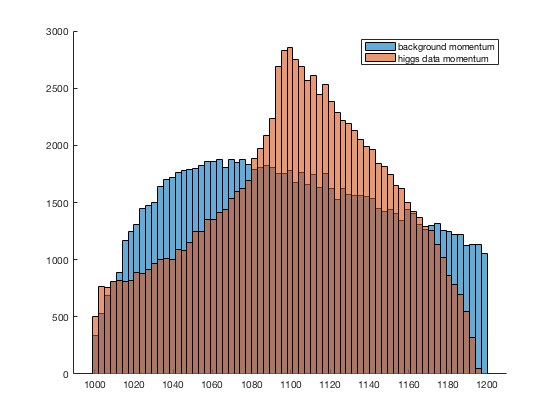

figure;
hold on
histogram(qPT);
histogram(hPT);
legend('background momentum','higgs data momentum');

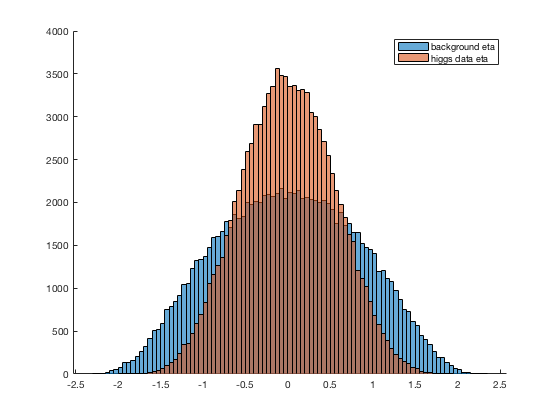

figure;
hold on
histogram(qETA);
histogram(hETA);
legend('background eta','higgs data eta');

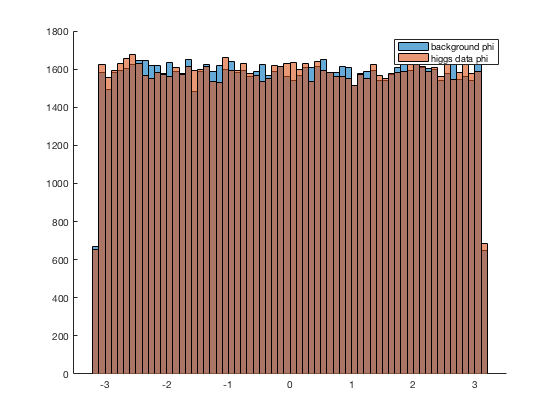

figure;
hold on
histogram(qPHI);
histogram(hPHI);
legend('background phi','higgs data phi');

figure;
hold on
histogram(qMASS);
histogram(hMASS);
legend('background mass','higgs data mass');

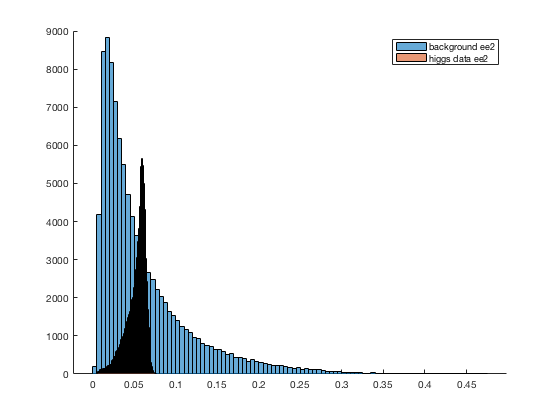

figure;
hold on
histogram(qEE2);
histogram(hEE2);
legend('background ee2','higgs data ee2');

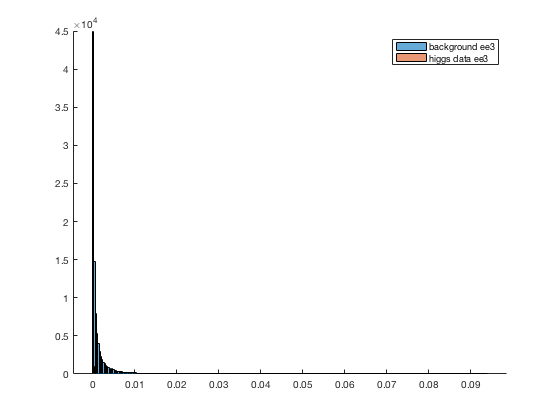

figure;
hold on
histogram(qEE3);
histogram(hEE3);
legend('background ee3','higgs data ee3');

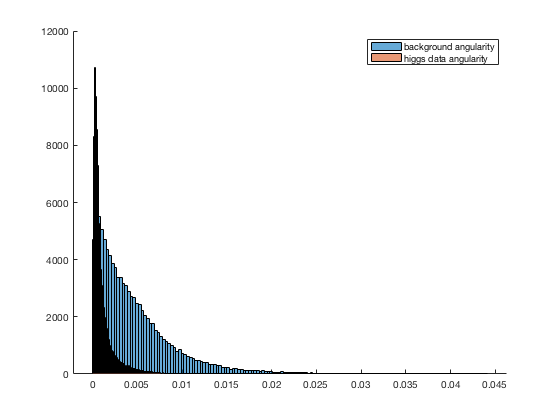

figure;
hold on
histogram(qANG);
histogram(hANG);
legend('background angularity','higgs data angularity');

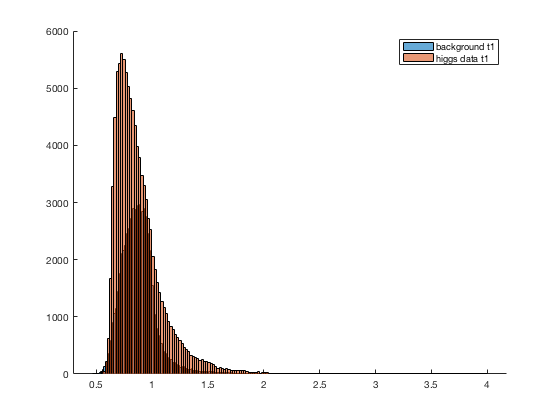

figure;
hold on
histogram(qT1);
histogram(hT1);
legend('background t1','higgs data t1');

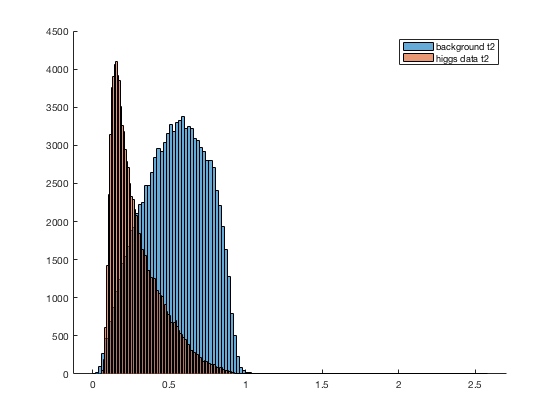

figure;
hold on
histogram(qT2);
histogram(hT2);
legend('background t2','higgs data t2');

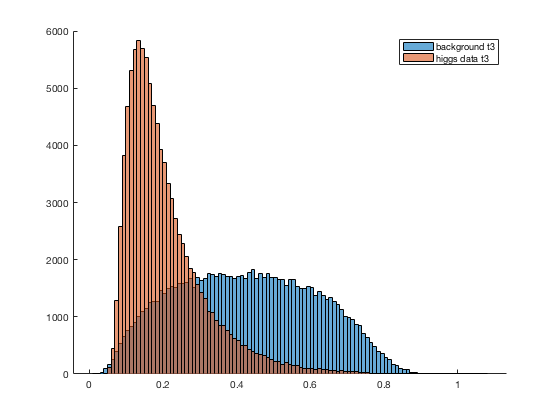

figure;
hold on
histogram(qT3);
histogram(hT3);
legend('background t3','higgs data t3');

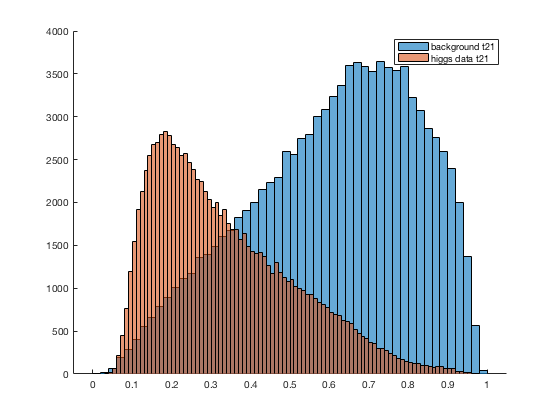

figure;
hold on
histogram(qT21);
histogram(hT21);
legend('background t21','higgs data t21');

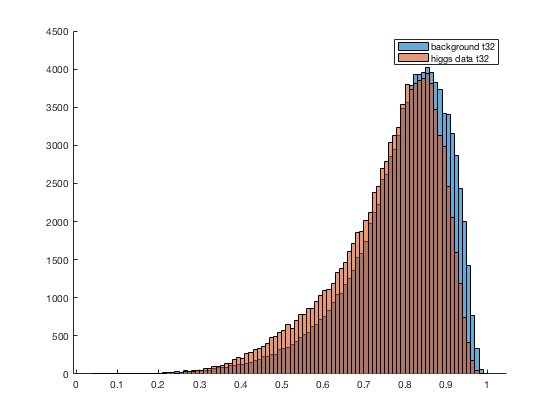

figure;
hold on
histogram(qT32);
histogram(hT32);
legend('background t32','higgs data t32');

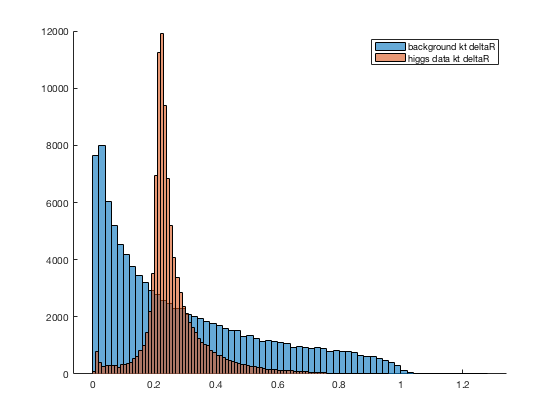

figure;
hold on
histogram(qKTDELTAR);
histogram(hKTDELTAR);
legend('background kt deltaR','higgs data kt deltaR');

*Can you identify another feature as discriminative as mass feature (i.e. equal or better significance after feature cut)*

I think T3, angularity or kt deltaR could function well to get better significance after feature cuts as there seem to be pretty simple mass cuts as the data sets have values where they (the background and the higgs data, that is) do not overlap much.

*Set B of plots with your optimal mass cuts*

Now I want to look at the same plots as above, except for data that matches my mass cut.

First, I want to find the data with each feature associated with my mass cut.

massCutQ = (qMASS >= 125 & qMASS <= 128)

massCutQ = 1×100000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


massCutH = (hMASS >= 125 & hMASS <= 128)

massCutH = 1×100000 logical array
   1   1   1   0   0   1   0   1   1   0   0   1   1   1   1   0   0   0   0   0   0   1   0   1   1   1   1   1   0   1   1   0   1   0   0   0   1   1   1   1   0   0   0   1   0   1   0   1   1   0


The above should give me two vectors where each value is either a 1 or a 0. 1 corresponds to "this data point is in this range," and 0 corresponds to "this data point is not in the range." I can then grab all of the points from my features that correspond to exactly these data points, since each vector of my features is of equal length.

Now, I can plot each feature with the "optimum" mass cut I found in part 2.

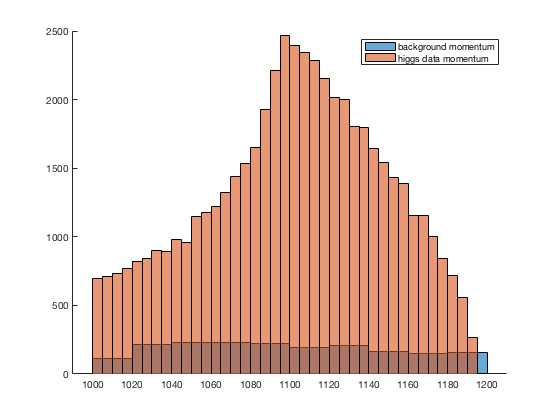

figure;
hold on
histogram(qPT(massCutQ));
histogram(hPT(massCutH));
legend('background momentum','higgs data momentum');

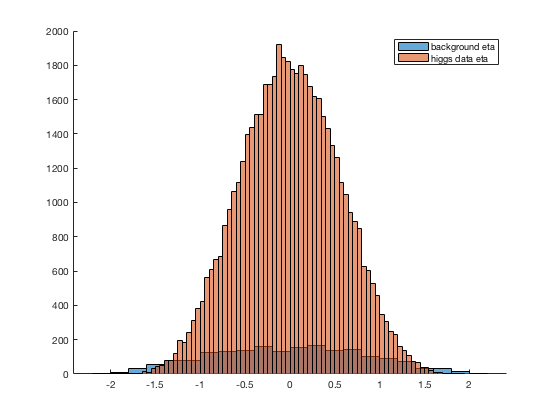

figure;
hold on
histogram(qETA(massCutQ));
histogram(hETA(massCutH));
legend('background eta','higgs data eta');

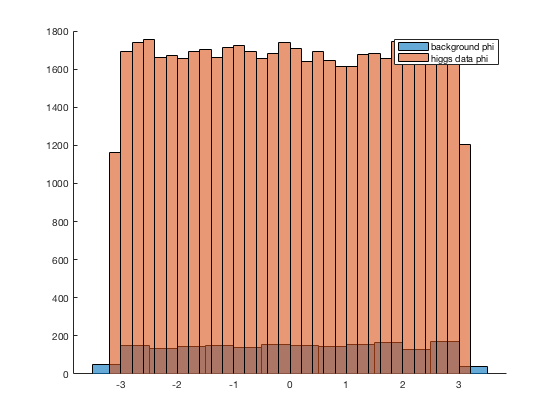

figure;
hold on
histogram(qPHI(massCutQ));
histogram(hPHI(massCutH));
legend('background phi','higgs data phi');

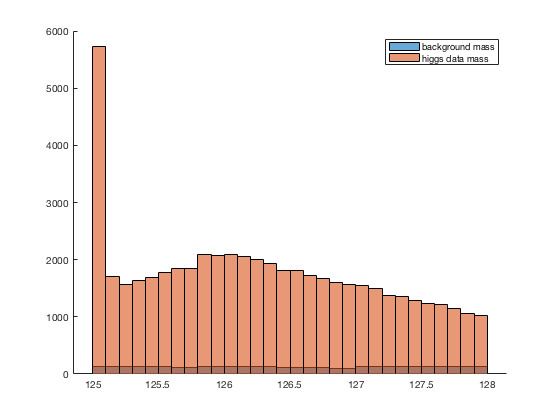

figure;
hold on
histogram(qMASS(massCutQ));
histogram(hMASS(massCutH));
legend('background mass','higgs data mass');

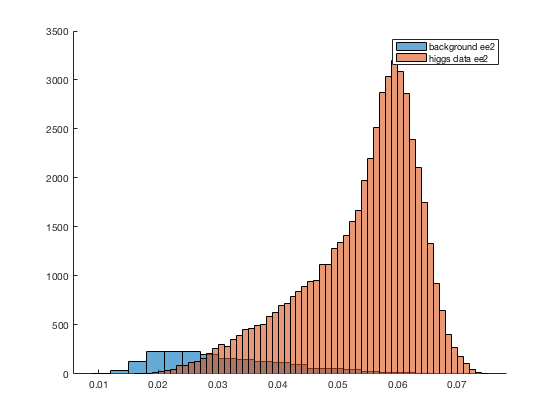

figure;
hold on
histogram(qEE2(massCutQ));
histogram(hEE2(massCutH));
legend('background ee2','higgs data ee2');

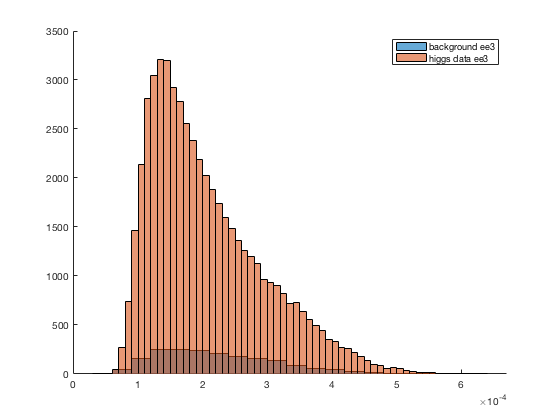

figure;
hold on
histogram(qEE3(massCutQ));
histogram(hEE3(massCutH));
legend('background ee3','higgs data ee3');

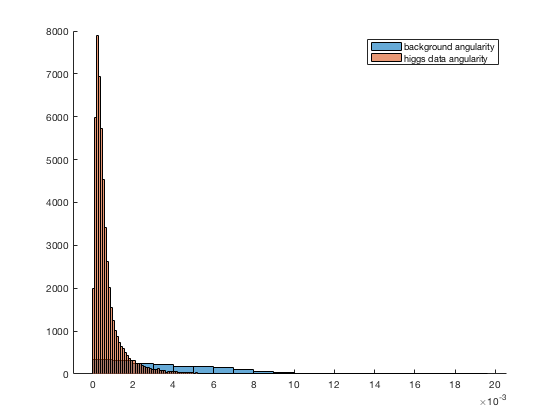

figure;
hold on
histogram(qANG(massCutQ));
histogram(hANG(massCutH));
legend('background angularity','higgs data angularity');

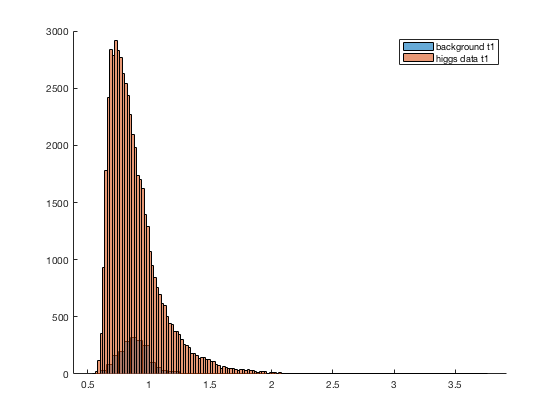

figure;
hold on
histogram(qT1(massCutQ));
histogram(hT1(massCutH));
legend('background t1','higgs data t1');

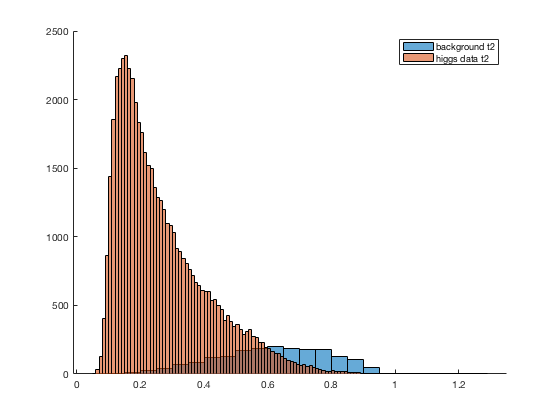

figure;
hold on
histogram(qT2(massCutQ));
histogram(hT2(massCutH));
legend('background t2','higgs data t2');

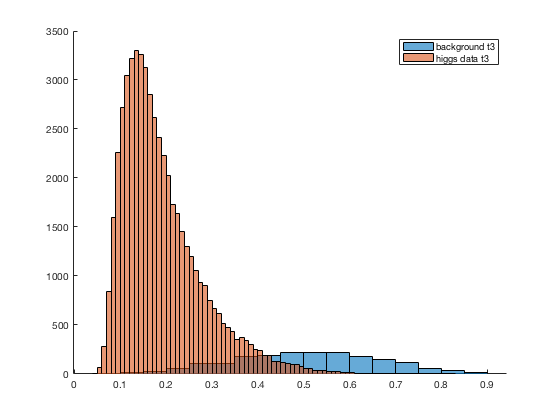

figure;
hold on
histogram(qT3(massCutQ));
histogram(hT3(massCutH));
legend('background t3','higgs data t3');

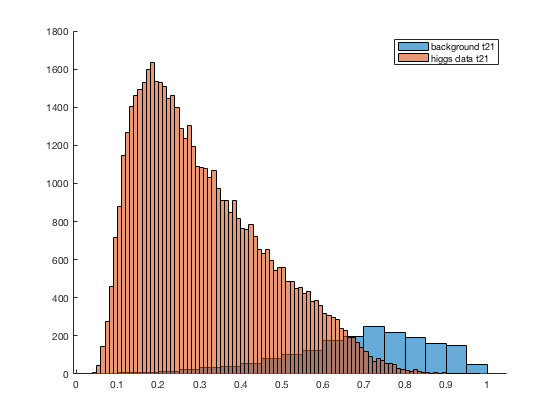

figure;
hold on
histogram(qT21(massCutQ));
histogram(hT21(massCutH));
legend('background t21','higgs data t21');

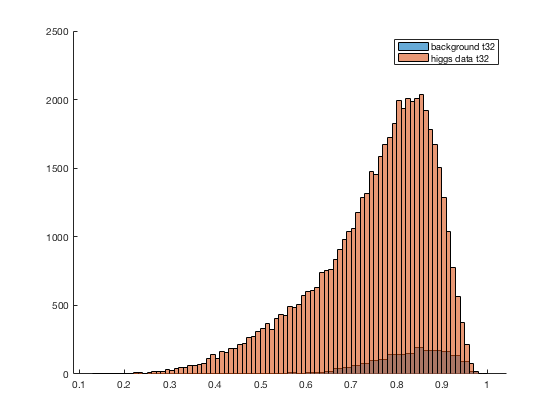

figure;
hold on
histogram(qT32(massCutQ));
histogram(hT32(massCutH));
legend('background t32','higgs data t32');

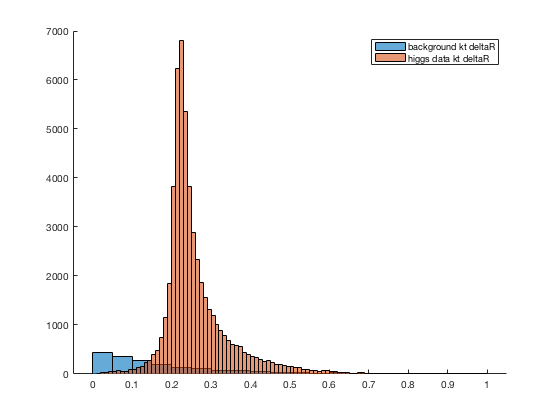

figure;
hold on
histogram(qKTDELTAR(massCutQ));
histogram(hKTDELTAR(massCutH));
legend('background kt deltaR','higgs data kt deltaR');

*Can you identify additional feature to further improve expected significance?*

This mass cut seems very successful, actually. Almost every single data set looks like there could be a really good cut that would improve the significance even more. Most notably, angularity has a high peak in the Higgs data, while the background data seems distributed over the entire range, making it a very good candidate for another cut to improve the expected significance.

**Problem 4: ***Optimize event selections using multiple features (if necessary)*

*Find a set of feature cuts which can help you to achieve the best significance.*

*Compare significance (before/after event selection) dervied in your pT samples to your lab partner. Describe your findings.*